## Modelando a antena emissora

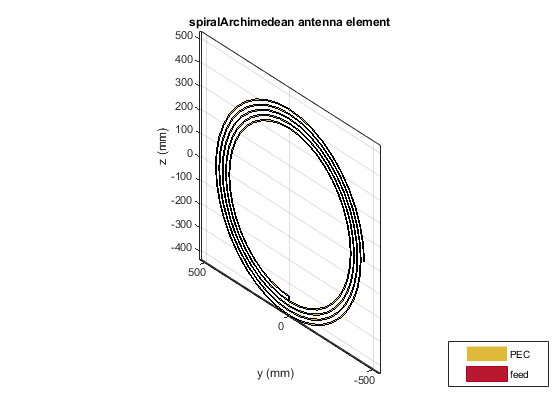

antena_emissora = spiralArchimedean("NumArms", 1, "Turns", 5, "InnerRadius", 0.35, "OuterRadius", 0.45, "tilt", 90, "TiltAxis", "Y");
show(antena_emissora);

## Calculando a impedancia da antena

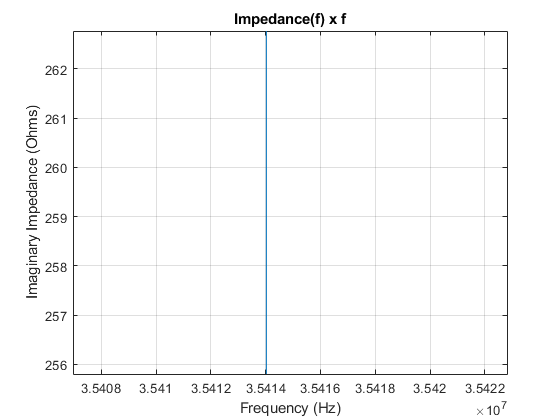

freq = 3.4e7:1e5:4.5e7;
impedancias = impedance(antena_emissora, freq);

plot(freq, imag(impedancias));
title("Impedance(f) x f");
xlabel("Frequency (Hz)");
ylabel("Imaginary Impedance (Ohms)");
grid("on");
ylim([-2e4 1.5e4]);
xlim([3.40e7 4.4e7]);

## Modelando a antena receptora

antena_receptora = spiralArchimedean("NumArms", 1, "Turns", 5, "InnerRadius", 0.35, "OuterRadius", 0.45, "tilt", 90, "TiltAxis", "Y");

## Simulando o acoplamento das antenas

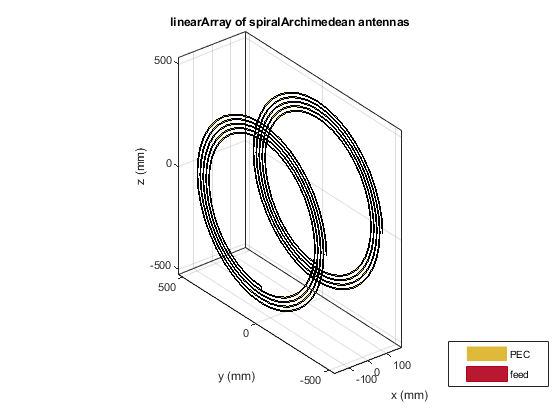

antenas = linearArray("Element", [antena_emissora antena_receptora], "ElementSpacing", 0.3);
show(antenas);


ganhos = sparameters(antenas, freq);

## Visualizando os ganhos

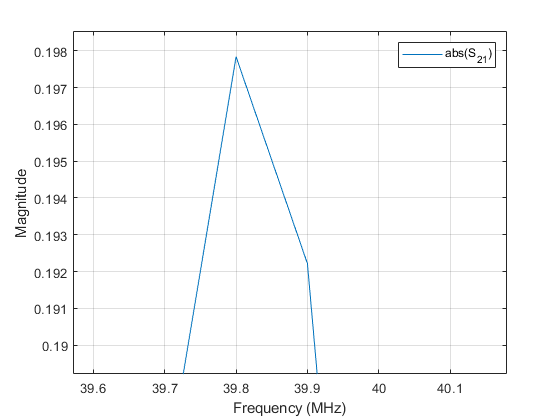

rfplot(ganhos, 2, 1, "abs");


% Essa frequência é a chamada frequência de ressonância. Ela é especial
% pois quando o sistema é alimentado pela mesma, a impedância é zerada
% fazendo com que o ganho em relação as duas antenas seja máximo. Como
% visto no gráfico das impedâncias, o ponto com maior ganho esta sobre
% alimentação da frequência de ressonância.

## Visualização 3D

dist = 0.05:0.025:0.5;
ganhos_ = zeros(length(dist), length(freq));
for i = 1:length(dist)
    antenas = linearArray("Element", [antena_emissora antena_receptora], "ElementSpacing", dist(i));
    ganho = sparameters(antenas, freq);
    ganhos_(i,:) = rfparam(ganho, 2, 1);
end

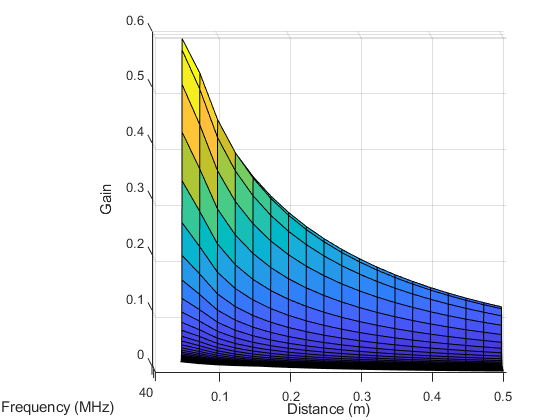

figure;
[x, y] = meshgrid(freq / 1e6, dist);
surf(x, y, abs(ganhos_));
xlabel("Frequency (MHz)");
ylabel("Distance (m)");
zlabel("Gain");

## Corrente ressonante

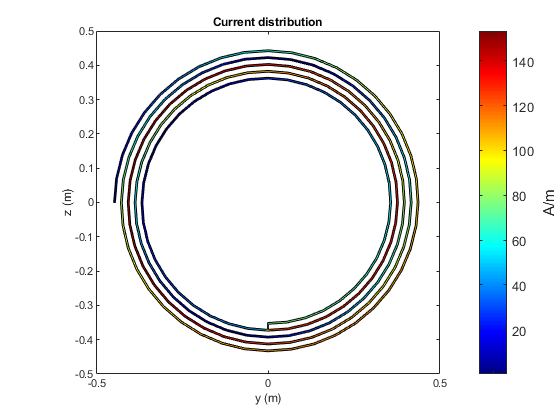

freq_ressonancia = 39.9e6;
current(antena_emissora, freq_ressonancia);

## Unindo os dois modelos

sigma = 22

sigma = 22

freq_critica = 3.5414e7

freq_critica = 35414000

wc = 2 * pi * freq_critica;
w = 2 .* pi .* freq;
L = sigma / wc;
C = 1 / (sigma * wc);

Zn = (1i .* w * L .* (1 ./ (1i .* w * C)))

Zn =   484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000  484.0000


Zd = (1i .* w * L + (1 ./ (1i .* w * C)))

Zd =    0.0000 - 1.7934i   0.0000 - 1.6640i   0.0000 - 1.5351i   0.0000 - 1.4066i   0.0000 - 1.2784i   0.0000 - 1.1506i   0.0000 - 1.0232i   0.0000 - 0.8962i   0.0000 - 0.7696i   0.0000 - 0.6433i   0.0000 - 0.5174i   0.0000 - 0.3919i   0.0000 - 0.2667i   0.0000 - 0.1419i   0.0000 - 0.0174i   0.0000 + 0.1067i   0.0000 + 0.2305i   0.0000 + 0.3539i   0.0000 + 0.4770i   0.0000 + 0.5997i   0.0000 + 0.7221i   0.0000 + 0.8442i   0.0000 + 0.9660i   0.0000 + 1.0874i   0.0000 + 1.2085i   0.0000 + 1.3292i   0.0000 + 1.4497i   0.0000 + 1.5698i   0.0000 + 1.6896i   0.0000 + 1.8091i   0.0000 + 1.9283i   0.0000 + 2.0472i   0.0000 + 2.1657i   0.0000 + 2.2840i   0.0000 + 2.4020i   0.0000 + 2.5197i   0.0000 + 2.6370i   0.0000 + 2.7541i   0.0000 + 2.8709i   0.0000 + 2.9874i   0.0000 + 3.1036i   0.0000 + 3.2196i   0.0000 + 3.3352i   0.0000 + 3.4506i   0.0000 + 3.5657i   0.0000 + 3.6805i   0.0000 + 3.7951i   0.0000 + 3.9093i   0.0000 + 4.0234i   0.0000 + 4.1371i


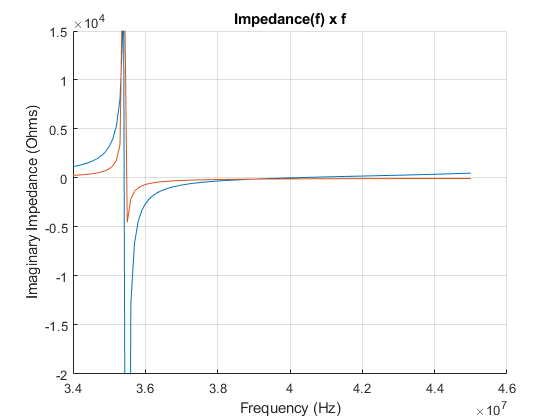

Za = Zn ./ Zd;

Z = Za + 4 * i*L .* w;

clf("reset");
hold on
plot(freq, imag(impedancias));
plot(freq, imag(Z));
hold off

title("Impedance(f) x f");
xlabel("Frequency (Hz)");
ylabel("Imaginary Impedance (Ohms)");
grid("on");
ylim([-2e4 1.5e4]);

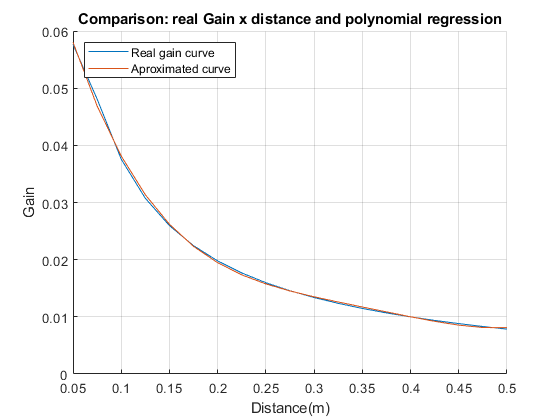

w = 2 * pi * freq_ressonancia;
Rc = 1;
M = 0:1e-11:4.9213e-09;
G = imag((1i * w .* M) ./ Rc);

re = polyfit(dist, abs(ganhos_(:,72)), 4);
M_dist = re * (Rc / w);

clf("reset");
hold on
plot(dist, abs(ganhos_(:,72)));
plot(dist, polyval(re, dist));
hold off

title("Comparison: real Gain x distance and polynomial regression");
xlabel("Distance(m)");
ylabel("Gain");
legend({'Real gain curve', 'Aproximated curve'}, "Location", "northwest");
grid("on");

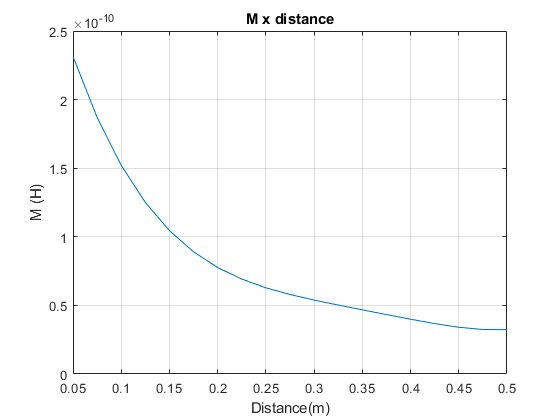

plot(dist, polyval(M_dist, dist));

title("M x distance");
xlabel("Distance(m)");
ylabel("M (H)");
grid("on");


% M(d) = 0.1566 * d⁴ - 0.22498 * d³ + 0.1212 * d² - 0.0304 * d + 0.0036